**Hand Measurements:**

E1 = [85 65 75 75 60 15 17 16 15];
E2 = [84 65 74 73 60 15 16 15 14];
E3 = [82 63 73 70 52 15 16 16 15];
E4 = [84 64 73 72 52 15 17 16 15];
E5 = [84 65 75 72 60 16 17 16 15];

E = [E1; E2; E3; E4; E5];

chosen_indices = [1, 2, 3, 4];

R_raw = mean(E(chosen_indices, :), 1);
R = round(R_raw, 1);
T = E5;

**Create database matrix and the test matrix.**

Create a database matrix “DB” of reference vectors, and a matrix “TEST” of test vectors. For this purpose, we will use your vectors, and the vectors attached as .mat files with this exercise.

Each column in the matrix DB consists of a reference vector of a different person, and the column index is the ID number of the person to whom the reference vector belongs. 

Each column in the matrix TEST is a test vector. The column index is also the ID number of the person to whom the test vector belongs.

load DB11a.mat
load T11a.mat

DB11a;
T11a;

R = R(:);
T = T(:);

DB = [R, DB11a];
TEST = [T, T11a];

**Identification Exercise**

*Carry out identification for the whole group, i.e. for all people in the test data matrix TEST. Then use the results to:*

*1) Calculate by hand the function P (k) for k = 1, 2, ....*

*P (k) indicates the chance (probability) that the correct identity is output in position k of IdLista. Draw the function P(k) that you calculated in a graph.*

*2) Calculate by hand the function TPIR (M) and draw it in a graph (the CMC curve). *

*TPIR (M) indicates the chance (probability) that the correct identity is output in the first M positions of the output list. * *TPIR (M) is obtained by summing up P(k) up to k = M.*

*Put also the values of P (k) and TPIR (M) in a table.*

*3) From TPIR (M), calculate the length of the list M to have a 90% chance that the correct identity is obtained in IdLista among the first M identities.*

*4) Find the two ID numbers that are the most and the least similar to your own ID. Also write down the distances of the two cases (how similar the hands are).*

***1)***

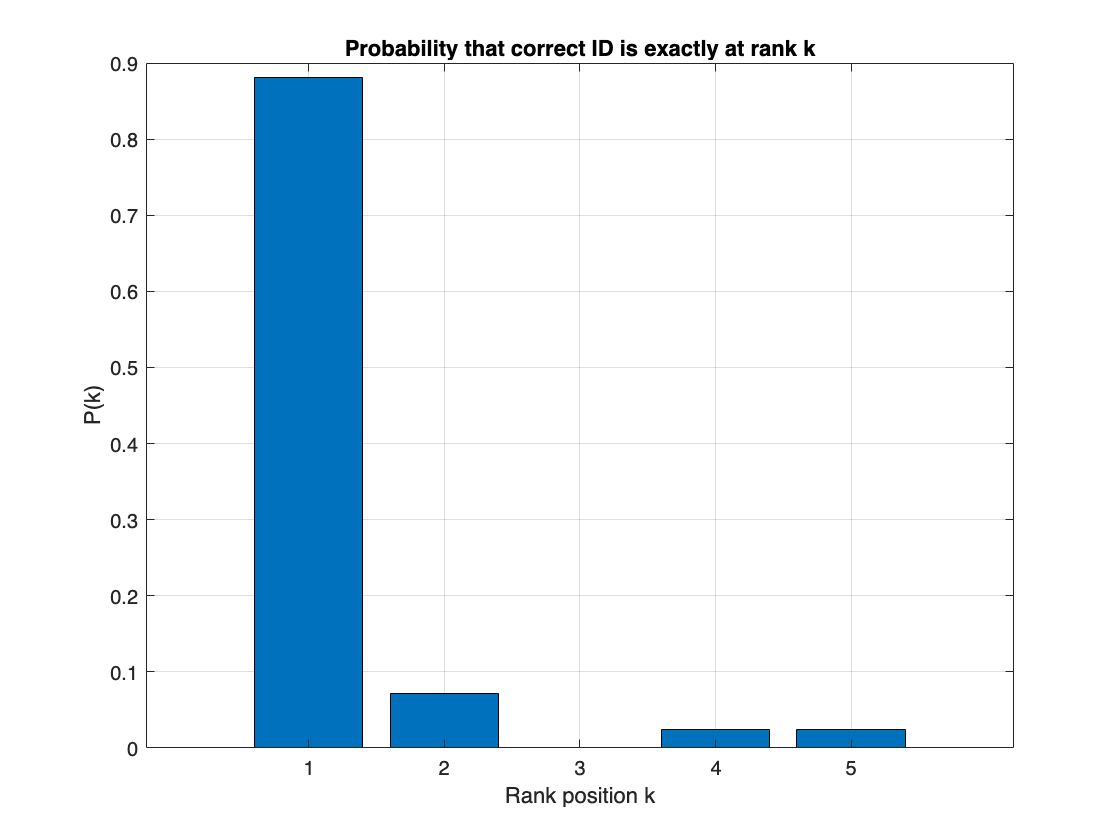

Ntests = size(TEST,2);
trueID = 1:Ntests;

rankPos = zeros(1,Ntests);
for j = 1:Ntests
    [IdLista, IdAvst] = MinDistClassID('eucl',DB,TEST,j);
    rankPos(j) = find(IdLista(:,1) == trueID(j), 1, 'first');
end

Kmax = max(rankPos);      % highest rank observed
P = zeros(1,Kmax);

for k = 1:Kmax
    P(k) = sum(rankPos == k) / Ntests;   % fraction of tests at rank k
end

% 3. Plot P(k) as a bar chart
figure;
bar(1:Kmax, P);
xlabel('Rank position k');
ylabel('P(k)');
title('Probability that correct ID is exactly at rank k');
grid on;
print('pk_bar','-depsc');   % Farbiges EPS

**2)**

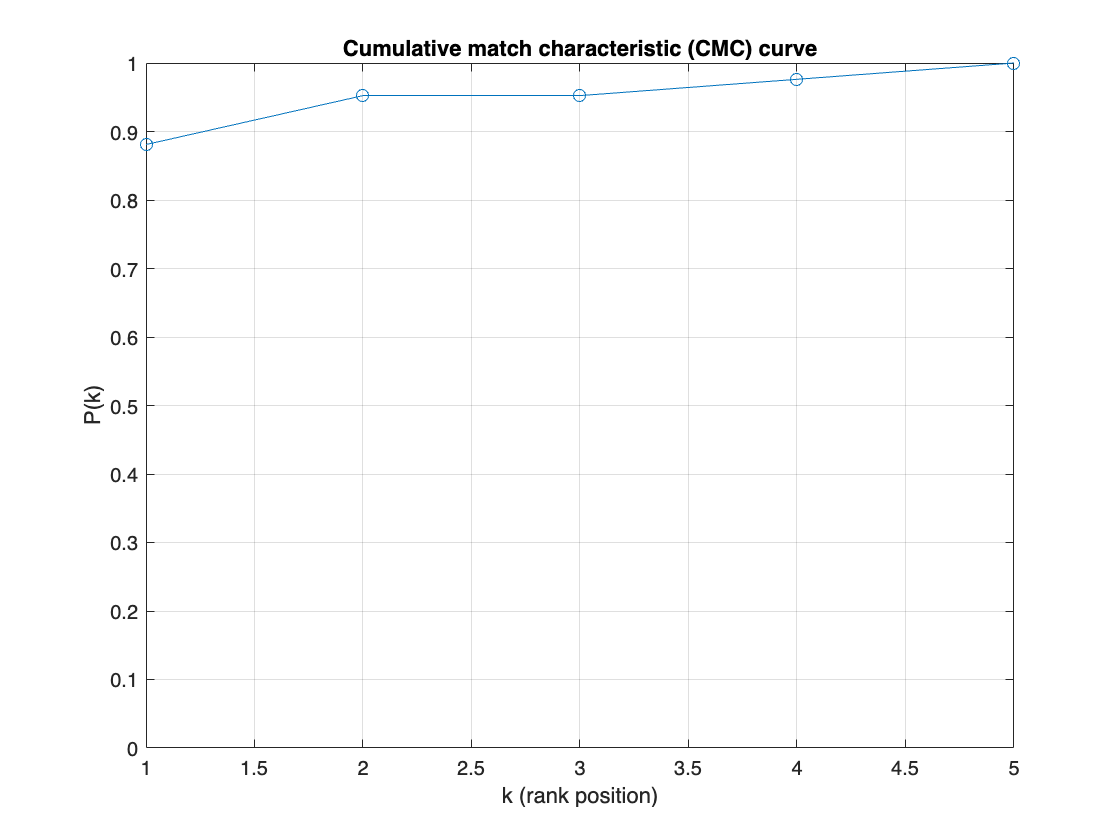

Kmax = max(rankPos);
P = zeros(1,Kmax);
for k = 1:Kmax
    P(k) = sum(rankPos <= k) / Ntests;
end

plot(1:Kmax, P, '-o');
xlabel('k (rank position)');
ylabel('P(k)');
title('Cumulative match characteristic (CMC) curve');
ylim([0,1])
grid on;
print('cmc_curve','-depsc');   % Farbiges EPS

*3) From TPIR (M), calculate the length of the list M to have a 90% chance that the correct identity is obtained in IdLista among the first M identities.*

len_M = find(P >= 0.9, 1, 'first')

len_M = 2

*4) Find the two ID numbers that are the most and the least similar to your own ID. Also write down the distances of the two cases (how similar the hands are).*

[IdLista, IdAvst] = MinDistClassID('eucl',DB,TEST,1);
most_sim = IdLista(1, :)

most_sim = 1

most_sim_dist = IdAvst(1, :)

most_sim_dist = 4.4215

least_sim = IdLista(end, :)

least_sim = 4

least_sim_dist = IdAvst(end, :)

least_sim_dist = 33.1310

**Verification Mode:**

To perform an authentication (one-to-one comparison) it is necessary to determine a value of the distance between the test vector and the reference vector which can be accepted as "sufficiently similar". This value is often called *threshold*.

The attached Matlab function **MinDistClassVER('eucl',DB,TEST,id,Th) **carries out the verification of the persons specified in the input parameter “id” using the threshold “Th”.

[VerId, VerAvst] = MinDistClassVER('eucl',DB,TEST,1,5) % test

VerId = 0

VerAvst = 4.4215

In order to estimate the error of the system, we should compute statistics of the output distances when hands from the same person and from different persons are compared. This can be done with the provided function:** [ShDist,OhDist]=DistNew('eucl',DB,TEST). **

Input parameters DB and TEST are the database data and test data. 

Output parameter ShDist contains the distances when hands from the same person are compared (ID=1 of DB with ID=1 of TEST, then ID=2 of DB with ID=2 of TEST, and so on) 

Output parameter OhDist contains the distances when hands from different persons are compared (ID=1 of DB with ID=2,3,4… of TEST, then ID=2 of DB with ID=1,3,4… of TEST, etc.)

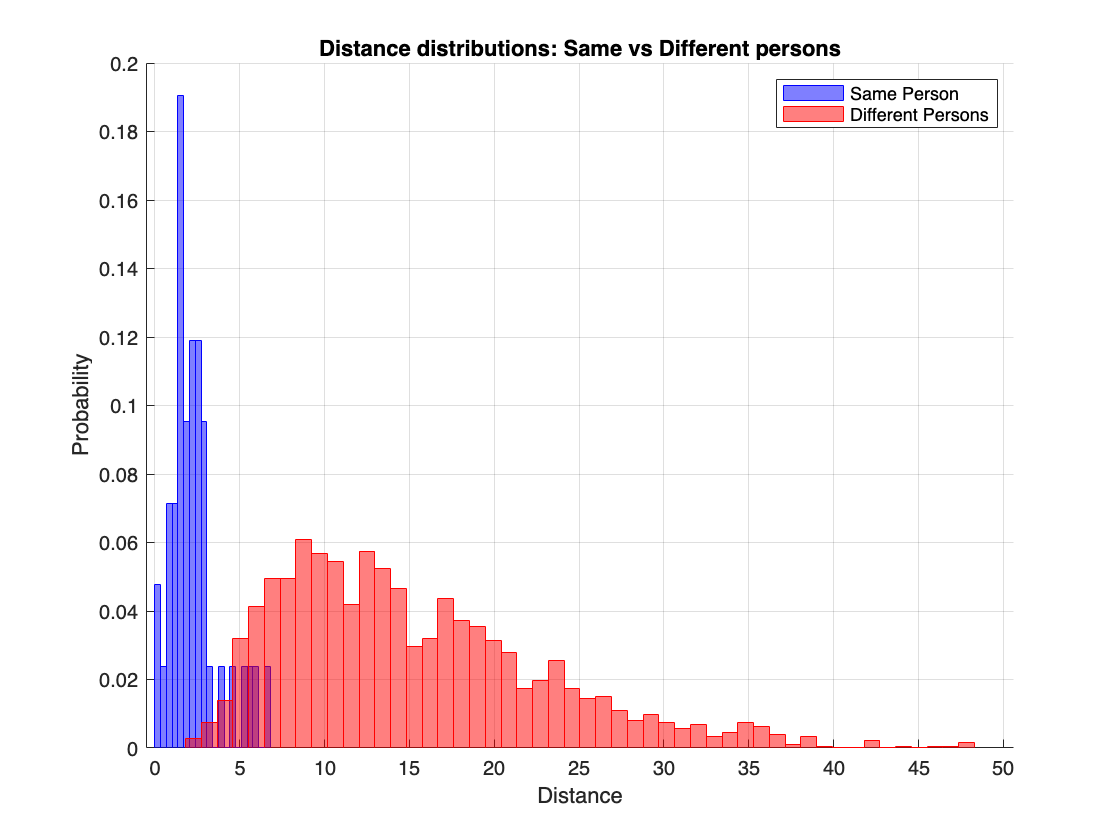

[ShDist,OhDist] = DistNew('eucl',DB,TEST);

figure;
hold on;

% Histogram for same-person distances
histogram(ShDist, 20, 'Normalization', 'probability', ...
    'FaceColor', 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'b');

% Histogram for different-person distances
histogram(OhDist, 50, 'Normalization', 'probability', ...
    'FaceColor', 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'r');

xlabel('Distance');
ylabel('Probability');
title('Distance distributions: Same vs Different persons');
legend('Same Person','Different Persons');
grid on;
hold off;
print('histograms','-depsc');

*With the help of the histograms you created earlier and shown in Figure = 100 (Genuine class) and figure = 101 (Impostor class), calculate and plot the probability of the FA error (= FAR) and FR error (= FRR) for various thresholds. You can also work directly with the distances in the vectors ShDist (Genuine) and OhDist (Impostor). Create a table with different thresholds and the number of errors of each type. *

*A Matlab command that you can use to calculate the number of FR errors at a specific threshold Th is: ****sum (ShDist> Th)****. Vary the value of Th and annotate both Th and the number of FR errors in a table. *

[ShDist,OhDist] = DistNew('eucl',DB,TEST);
th = linspace(0, 15, 200);

N_th = length(th);
FRR = zeros(1, N_th);
FAR = zeros(1, N_th);
FR_count = zeros(1, N_th);
FA_count = zeros(1, N_th);

for i = 1:length(th)
    % False Rejections (genuine > threshold)
    FR_count(i) = sum(ShDist > th(i));
    FRR(i) = FR_count(i) / numel(ShDist);

    % False Acceptances (impostor <= threshold)
    FA_count(i) = sum(OhDist <= th(i));
    FAR(i) = FA_count(i) / numel(OhDist);
end

% Create table for first few thresholds as an example
ErrorTable = table(th', FR_count', FA_count', FRR', FAR', ...
    'VariableNames', {'Threshold','FR_Errors','FA_Errors','FRR','FAR'});
disp(ErrorTable(1:200,:));  % show first 100 rows

    Threshold    FR_Errors    FA_Errors      FRR          FAR   
    _________    _________    _________    ________    _________

           0        40             0        0.95238            0
    0.075377        40             0        0.95238            0
     0.15075        40             0        0.95238            0
     0.22613        40             0        0.95238            0
     0.30151        40             0        0.95238            0
     0.37688        40             0        0.95238            0
     0.45226        40             0        0.95238            0
     0.52764        40             0        0.95238            0
     0.60302        39             0        0.92857            0
     0.67839        39             0        0.92857            0
     0.75377        38             0        0.904

**Seperate Tables:**

FRRTable = table(th', FR_count', FRR', ...
    'VariableNames', {'Threshold', 'FR_Errors', 'FRR'});
disp(FRRTable);

    Threshold    FR_Errors      FRR   
    _________    _________    ________

           0        40         0.95238
    0.075377        40         0.95238
     0.15075        40         0.95238
     0.22613        40         0.95238
     0.30151        40         0.95238
     0.37688        40         0.95238
     0.45226        40         0.95238
     0.52764        40         0.95238
     0.60302        39         0.92857
     0.67839        39         0.92857
     0.75377        38         0.90476
     0.82915        38         0.90476
     0.90452        38         0.90476
      0.9799        37         0.88095
      1.0553        36         0.85714
      1.1307        36         0.85714
       1.206        36         0.85714
      1.2814        34         0.80952
      1.3568        33         0.78571
      1.4322        32          0.7619
      1.5075        30         0.71429


FARTable = table(th', FA_count', FAR', ...
    'VariableNames', {'Threshold', 'FA_Errors', 'FAR'});
disp(FARTable); % preview

    Threshold    FA_Errors       FAR   
    _________    _________    _________

           0          0               0
    0.075377          0               0
     0.15075          0               0
     0.22613          0               0
     0.30151          0               0
     0.37688          0               0
     0.45226          0               0
     0.52764          0               0
     0.60302          0               0
     0.67839          0               0
     0.75377          0               0
     0.82915          0               0
     0.90452          0               0
      0.9799          0               0
      1.0553          0               0
      1.1307          0               0
       1.206          0               0
      1.2814          0               0
      1.3568          0               0
      1.4322          0               0
      1.5075     

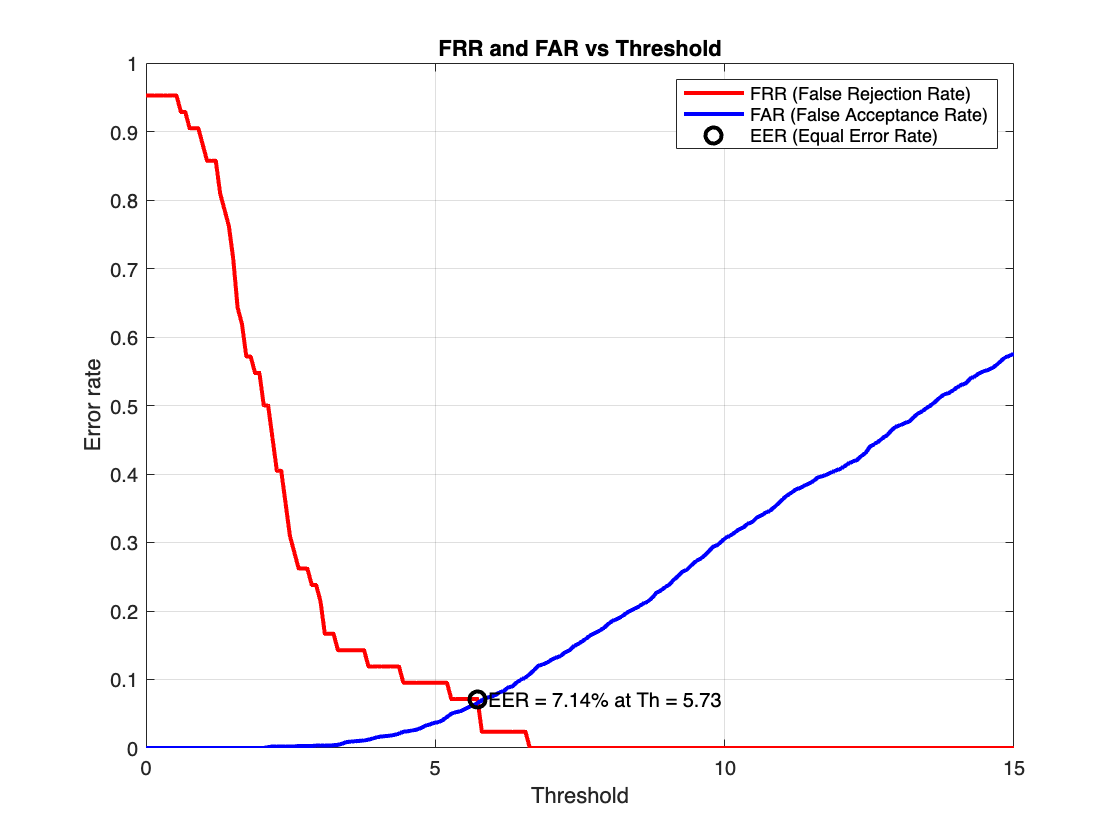

% Plot FRR and FAR
figure;
plot(th, FRR, 'r-', 'LineWidth', 2); hold on;
plot(th, FAR, 'b-', 'LineWidth', 2);
xlabel('Threshold');
ylabel('Error rate');

% Find Equal Error Rate (EER): the point where FAR ≈ FRR
[~, eer_idx] = min(abs(FRR - FAR));
eer_threshold = th(eer_idx);
eer_value = FRR(eer_idx); % or FAR(eer_idx), they’re ~equal

% Add EER to the plot
plot(eer_threshold, eer_value, 'ko', 'MarkerSize', 8, 'LineWidth', 2);
text(eer_threshold, eer_value, sprintf('  EER = %.2f%% at Th = %.2f', eer_value*100, eer_threshold));

title('FRR and FAR vs Threshold');
legend('FRR (False Rejection Rate)', 'FAR (False Acceptance Rate)', 'EER (Equal Error Rate)');
grid on;
print('eer_plot','-depsc');

**Choosing Threshholds: High Security vs. High Convenience**

% High Security (FAR <= 1%)
sec_candidates = find(FAR <= 0.01);
[~, sec_best] = min(FRR(sec_candidates));
sec_idx = sec_candidates(sec_best);
fprintf('High Security → Th = %.4f, FAR = %.2f%%, FRR = %.2f%%\n', ...
    th(sec_idx), FAR(sec_idx)*100, FRR(sec_idx)*100);

High Security → Th = 3.3166, FAR = 0.46%, FRR = 14.29%



% High Convenience (FRR <= 1%)
conv_candidates = find(FRR <= 0.01);
[~, conv_best] = min(FAR(conv_candidates));
conv_idx = conv_candidates(conv_best);
fprintf('High Convenience → Th = %.4f, FAR = %.2f%%, FRR = %.2f%%\n', ...
    th(conv_idx), FAR(conv_idx)*100, FRR(conv_idx)*100);

High Convenience → Th = 6.6332, FAR = 10.80%, FRR = 0.00%


save('DB_final.mat', 'DB');
save('TEST_final.mat', 'TEST');